clear; clc;

AEB KPI Extractor

% Set up project environment and add paths
projectRoot = '/Users/wangjianhai/02_ADAS/01_repo/01_Tools/01_matlab/01_kpi_extractor/AEB_KPI_Project';
addpath(genpath(projectRoot));
           
configPath = fullfile(projectRoot, 'config', 'Config.json')

configPath = '/Users/wangjianhai/02_ADAS/01_repo/01_Tools/01_matlab/01_kpi_extractor/AEB_KPI_Project/config/Config.json'

Processing MF4 files...
Found 1 MF4 file(s) to process...
/data/AEB_KPI_Project/docker/mdf2matSim.py:339: FutureWarning: The behavior of DataFrame concatenation with empty or all-NA entries is deprecated. In a future version, this will no longer exclude empty or all-NA columns when determining the result dtypes. To retain the old behavior, exclude the relevant entries before the concat operation.
  raster = pd.concat([raster, pd.DataFrame({'Variable': [generic_name], 'Raster': [r]})], ignore_index=True)
Reading MDF file: /data/rawdata/roadcast_debug_converted.mf4
DataFrame columns: ['latActAccel', 'longActAccel', 'aebTargetDecel', 'egoSpeed', 'throttleValue', 'aebAbortFromVcs', 'brakePedalPressed', 'steerWheelAngle', 'steerWheelAngleSpeed', 'yawRate', 'longGap', 'targetId', 'ttc', 'aebFullState', 'aebPartialState']
DataFrame shape: (84902, 15)
Saved /data/rawdata/roadcast_debug_converted.mat
Processing complete.
Processed: roadcast_debug_converted.mf4, saved to /Users/wangjianhai/02_AD

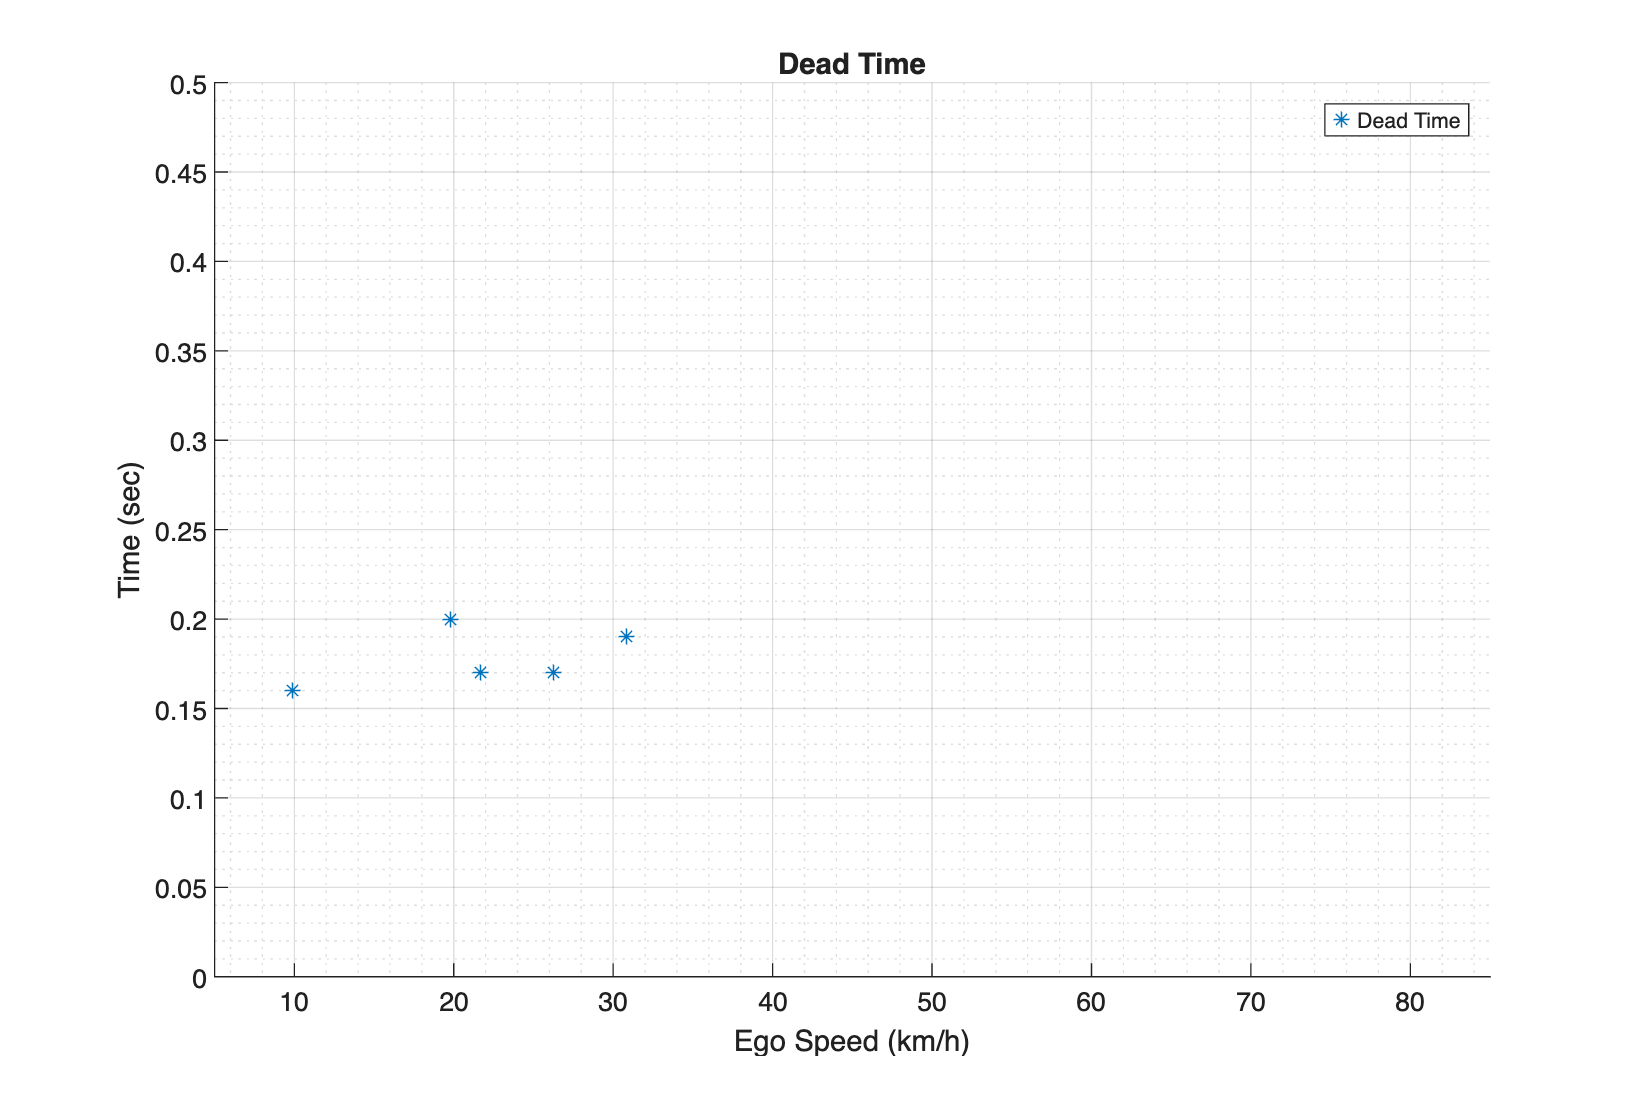

Graph 3 plotEnabled = isVehStopped


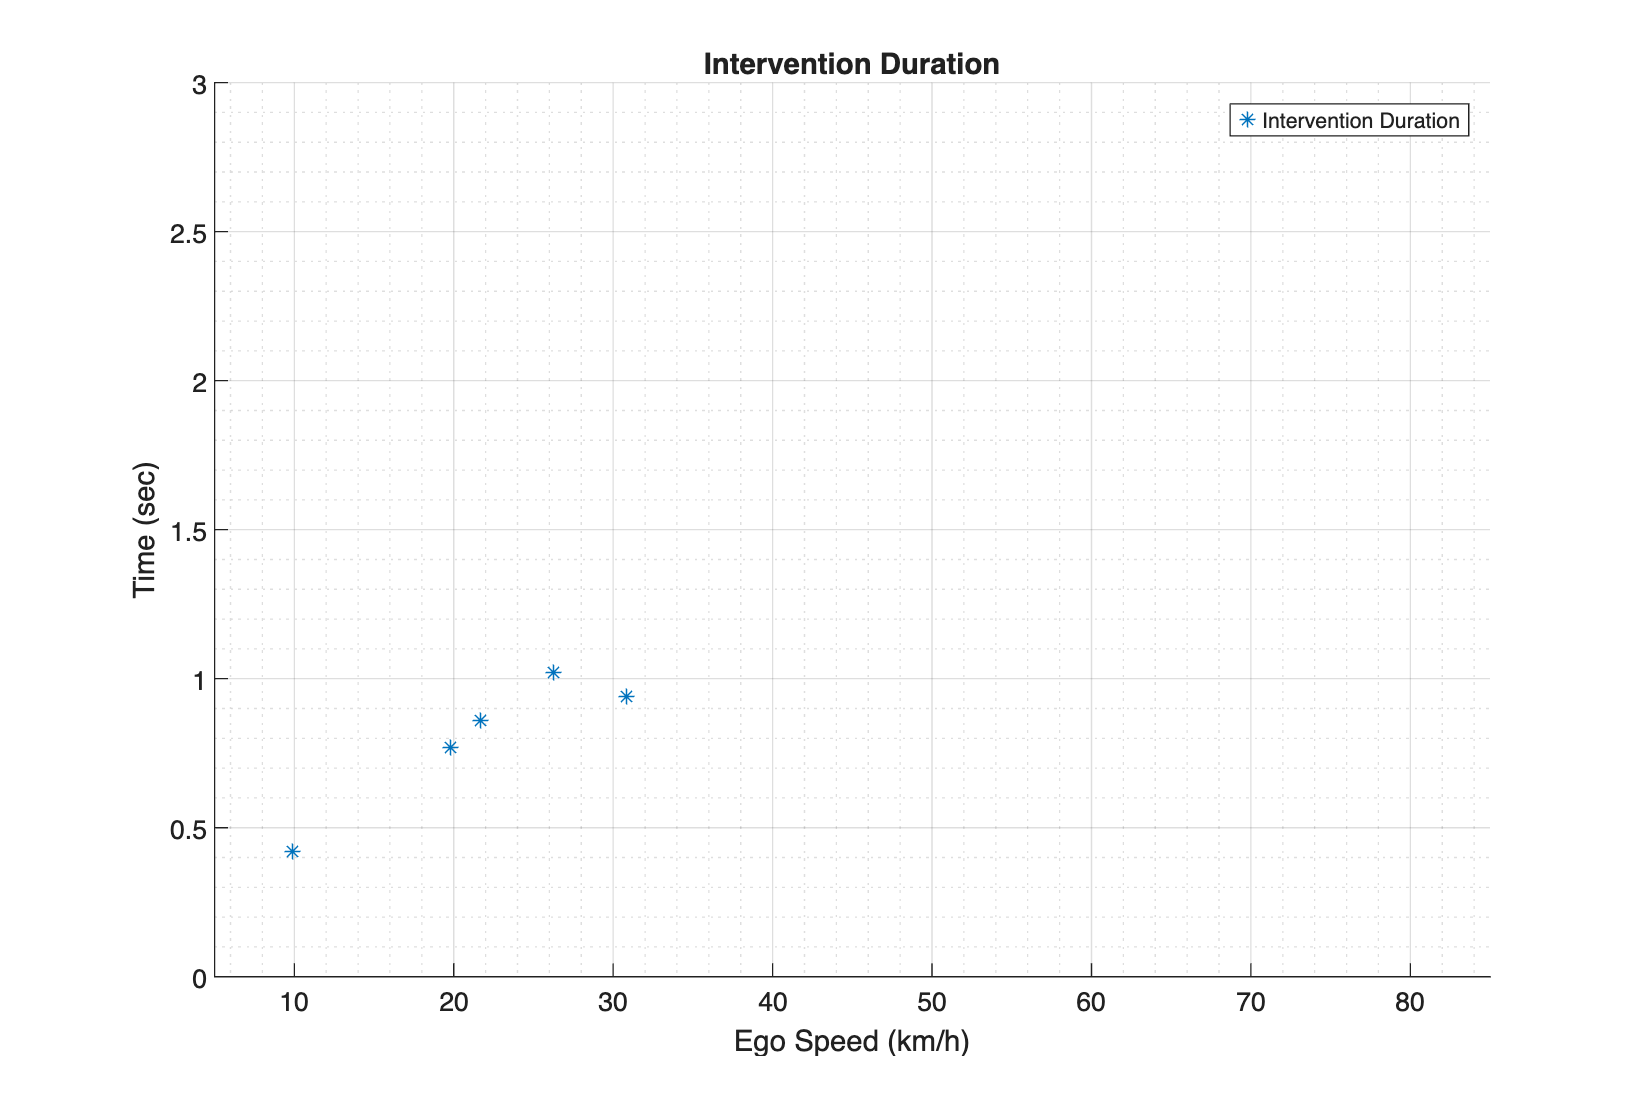

Graph 4 plotEnabled = true


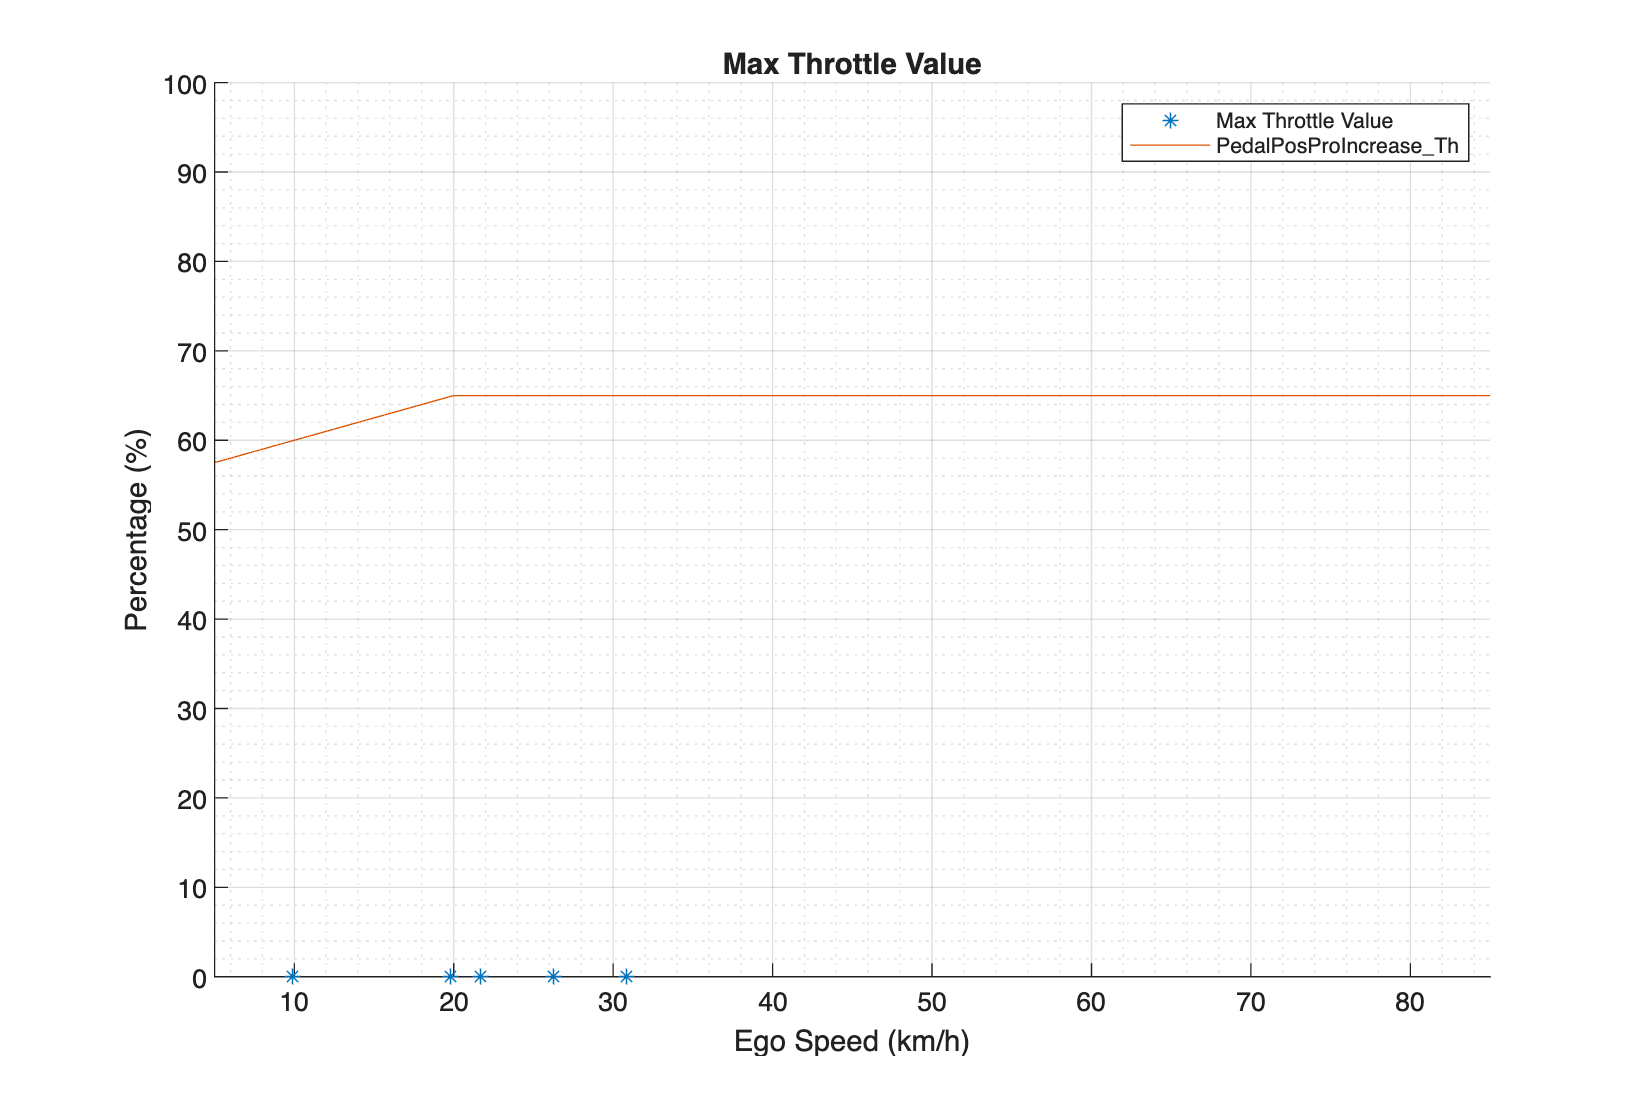

Graph 5 plotEnabled = true


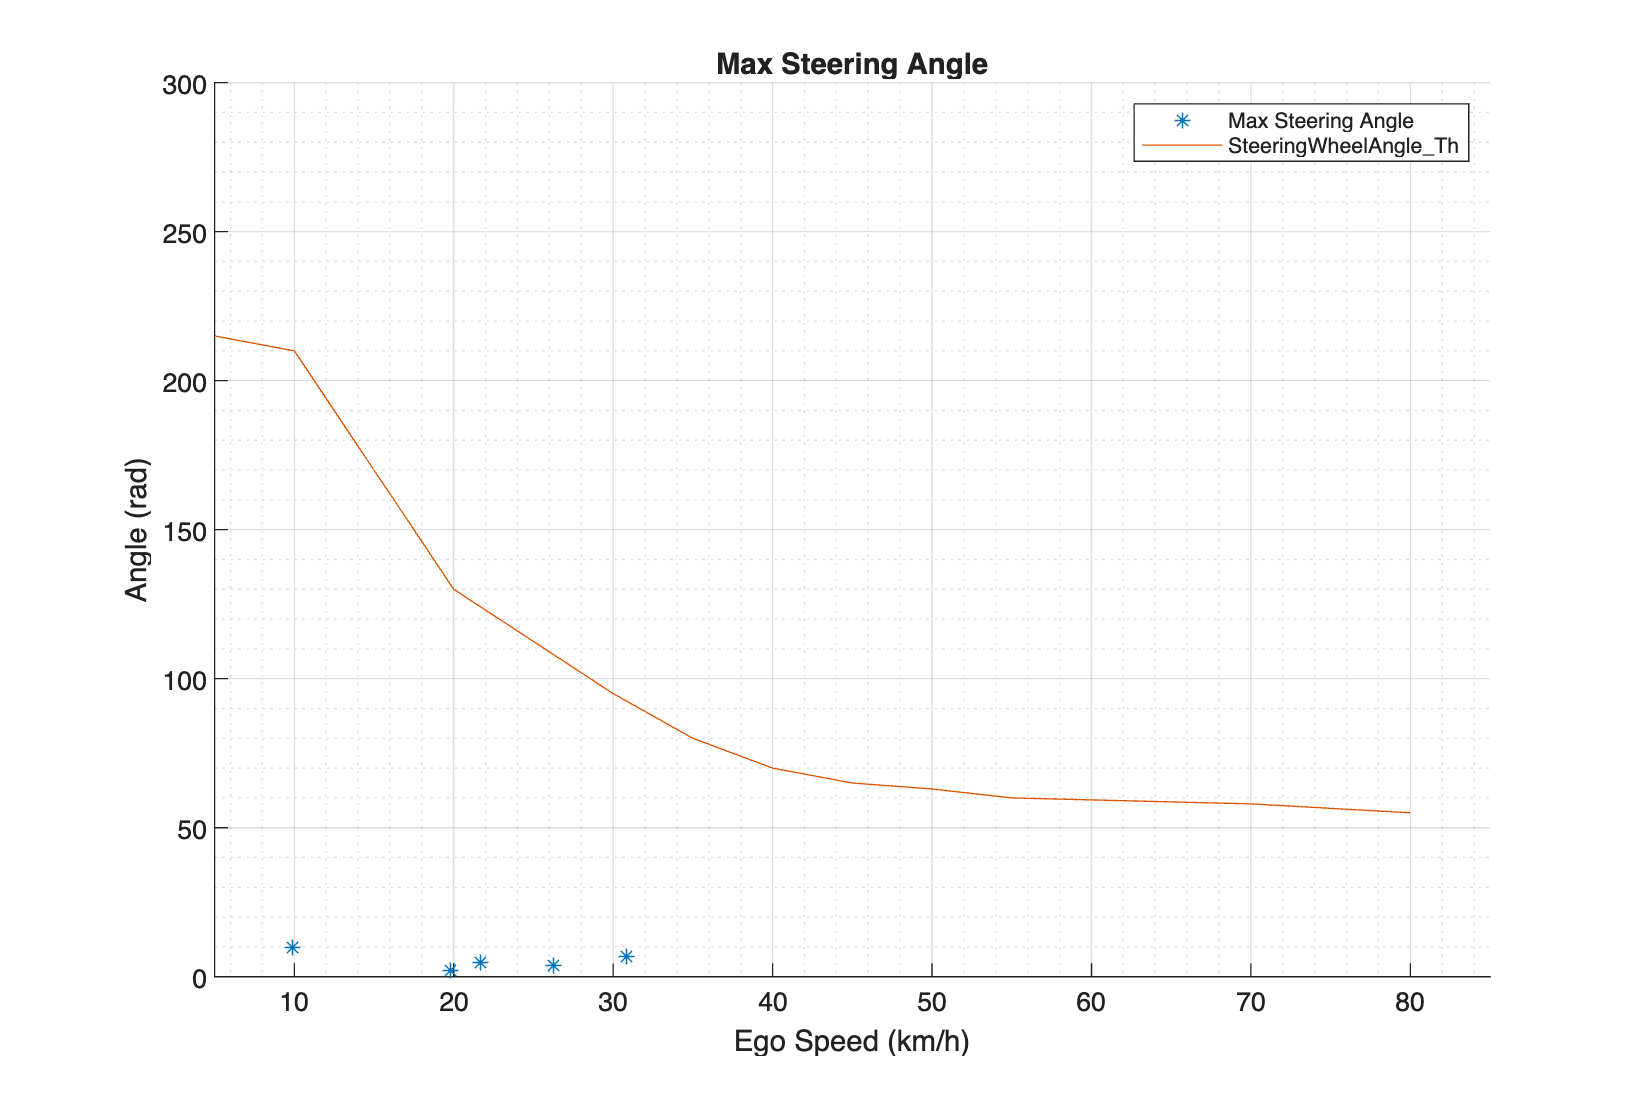

Graph 6 plotEnabled = true


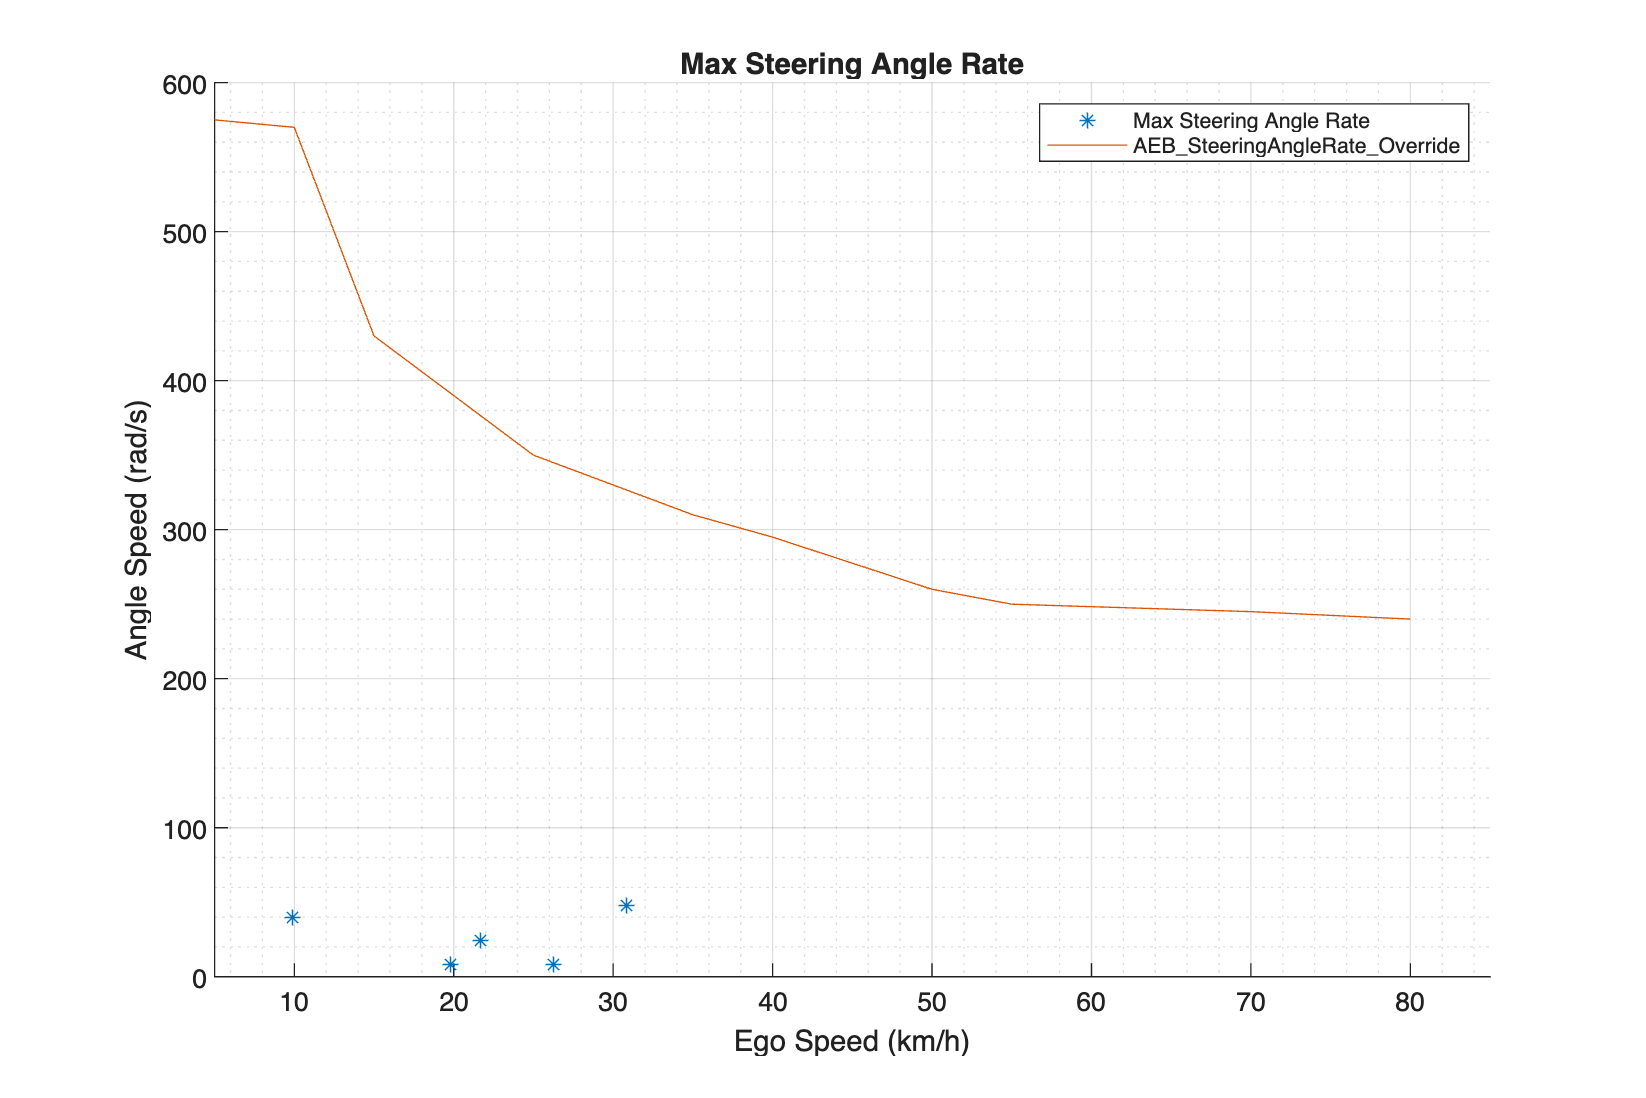

Graph 7 plotEnabled = true


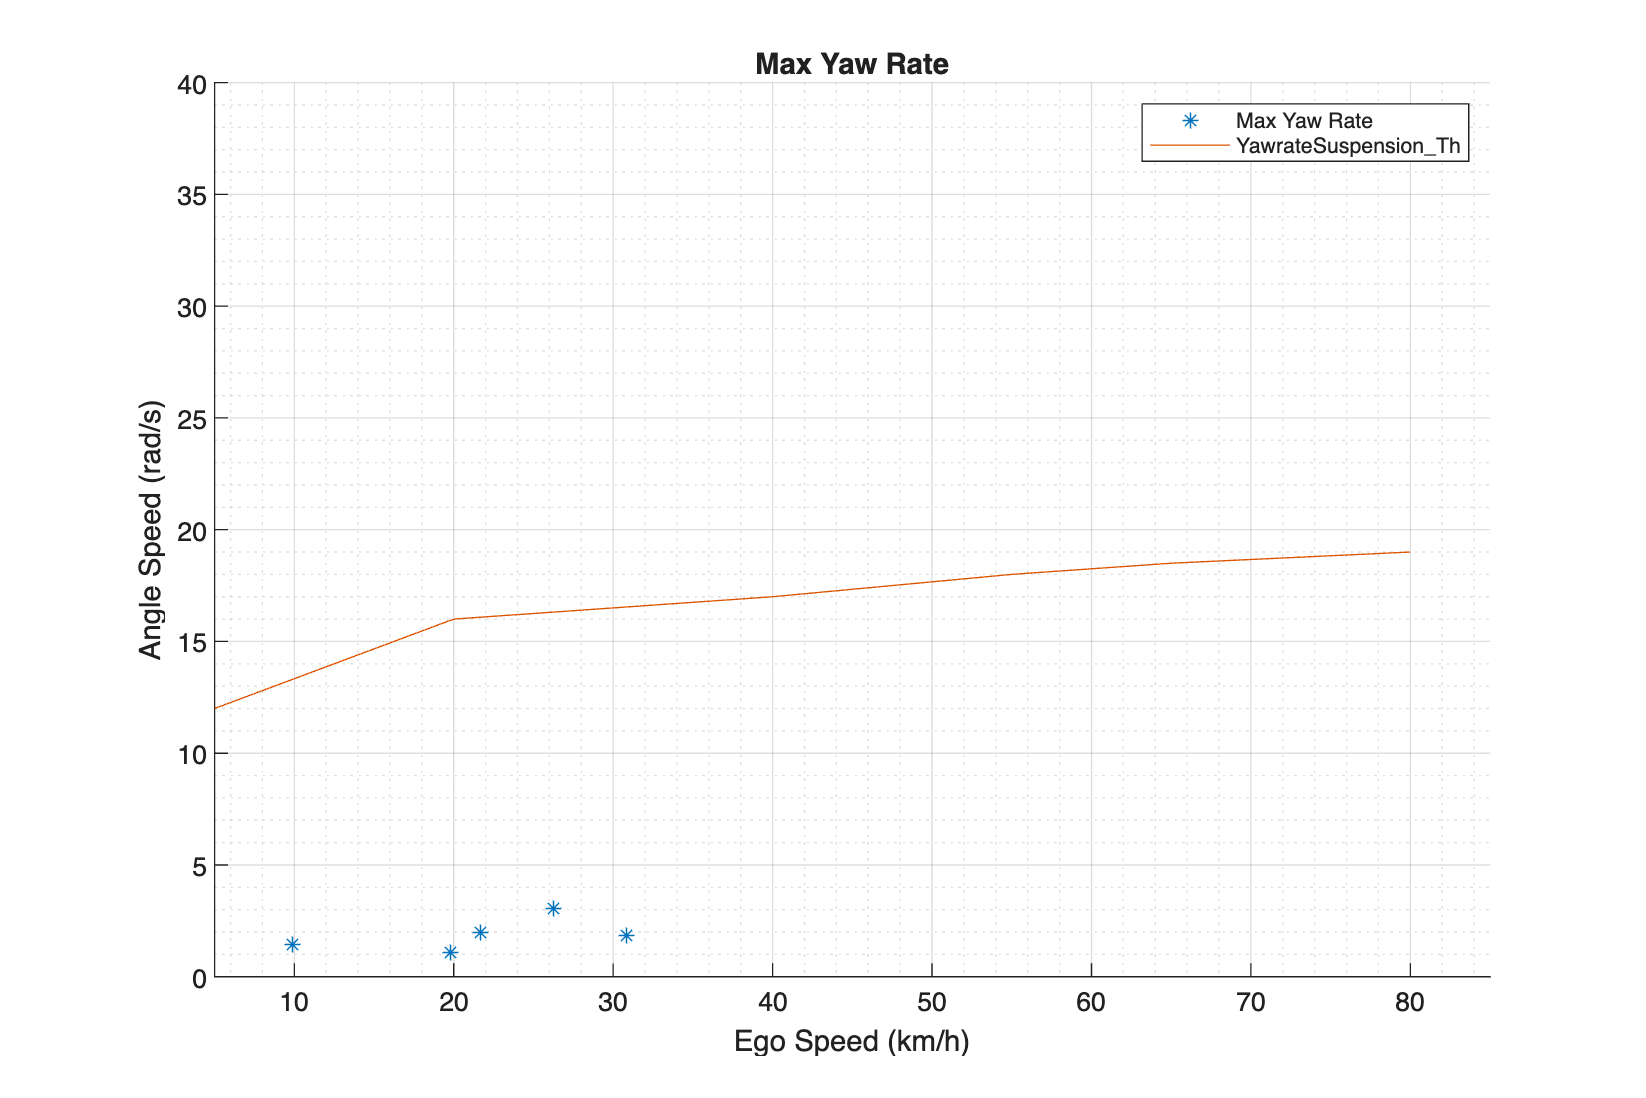

Graph 8 plotEnabled = true


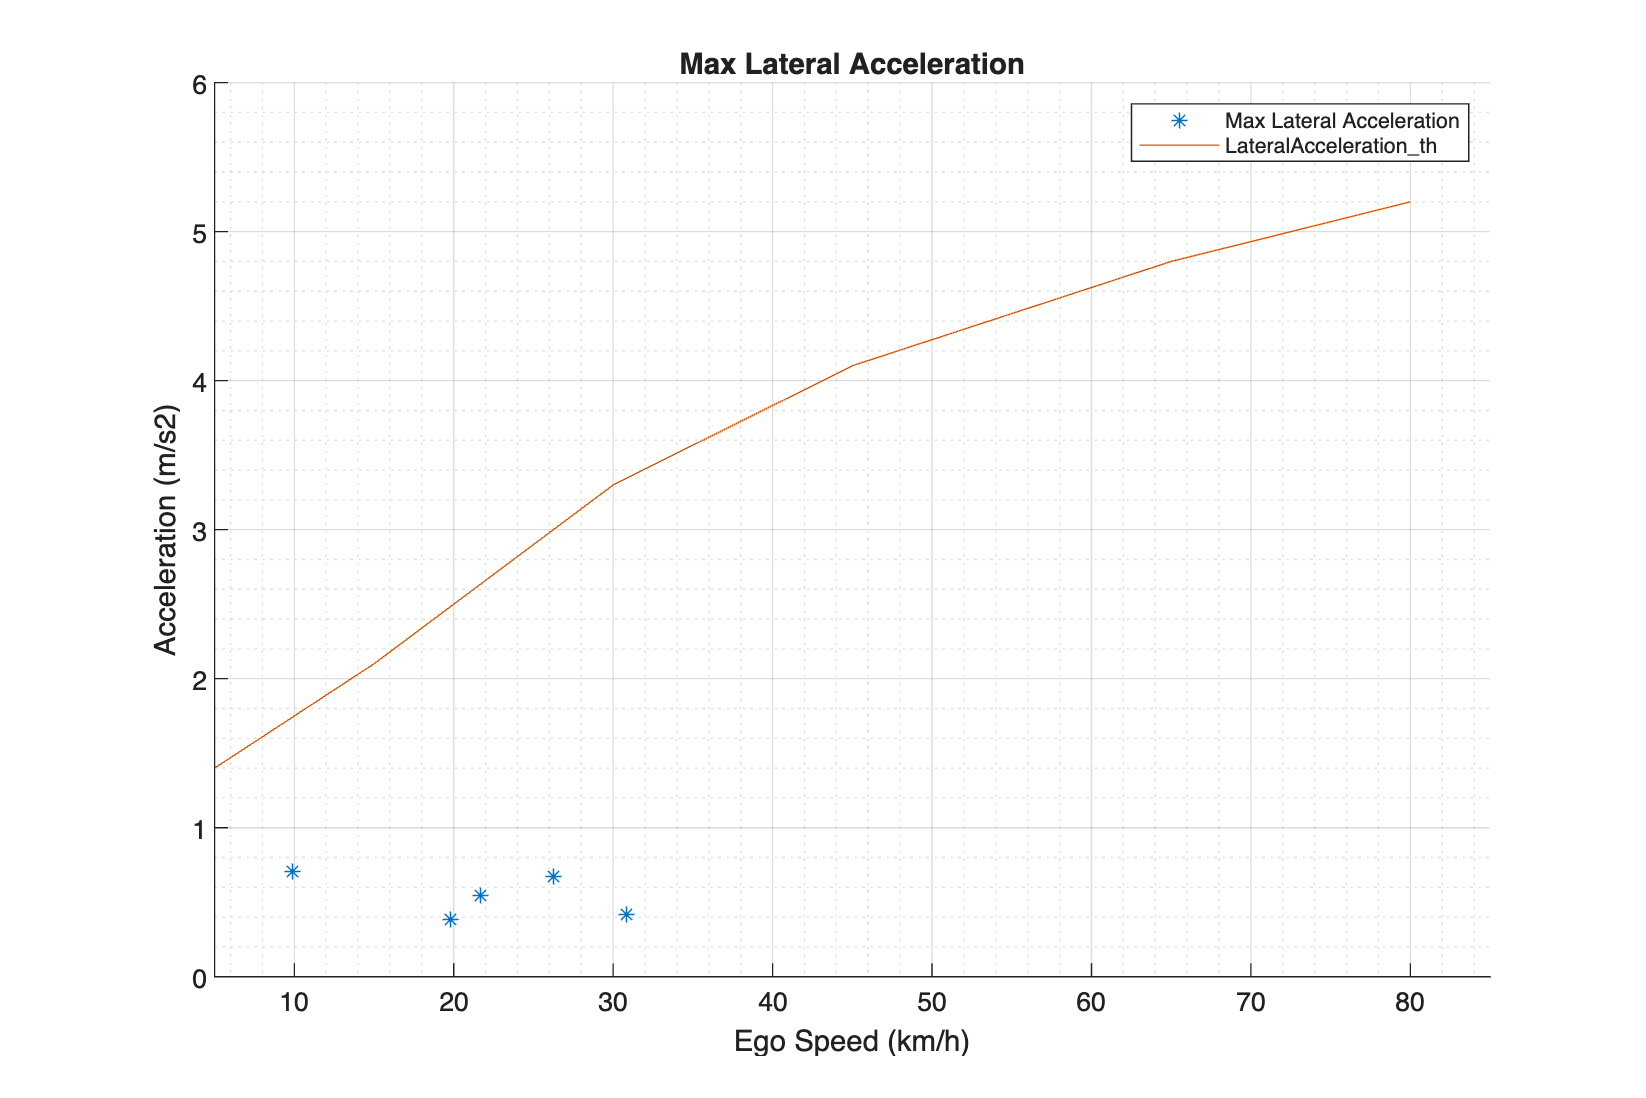

Graph 9 plotEnabled = true
Graph 10 plotEnabled = true
Graph 11 plotEnabled = true
Graph 12 plotEnabled = isVehStopped


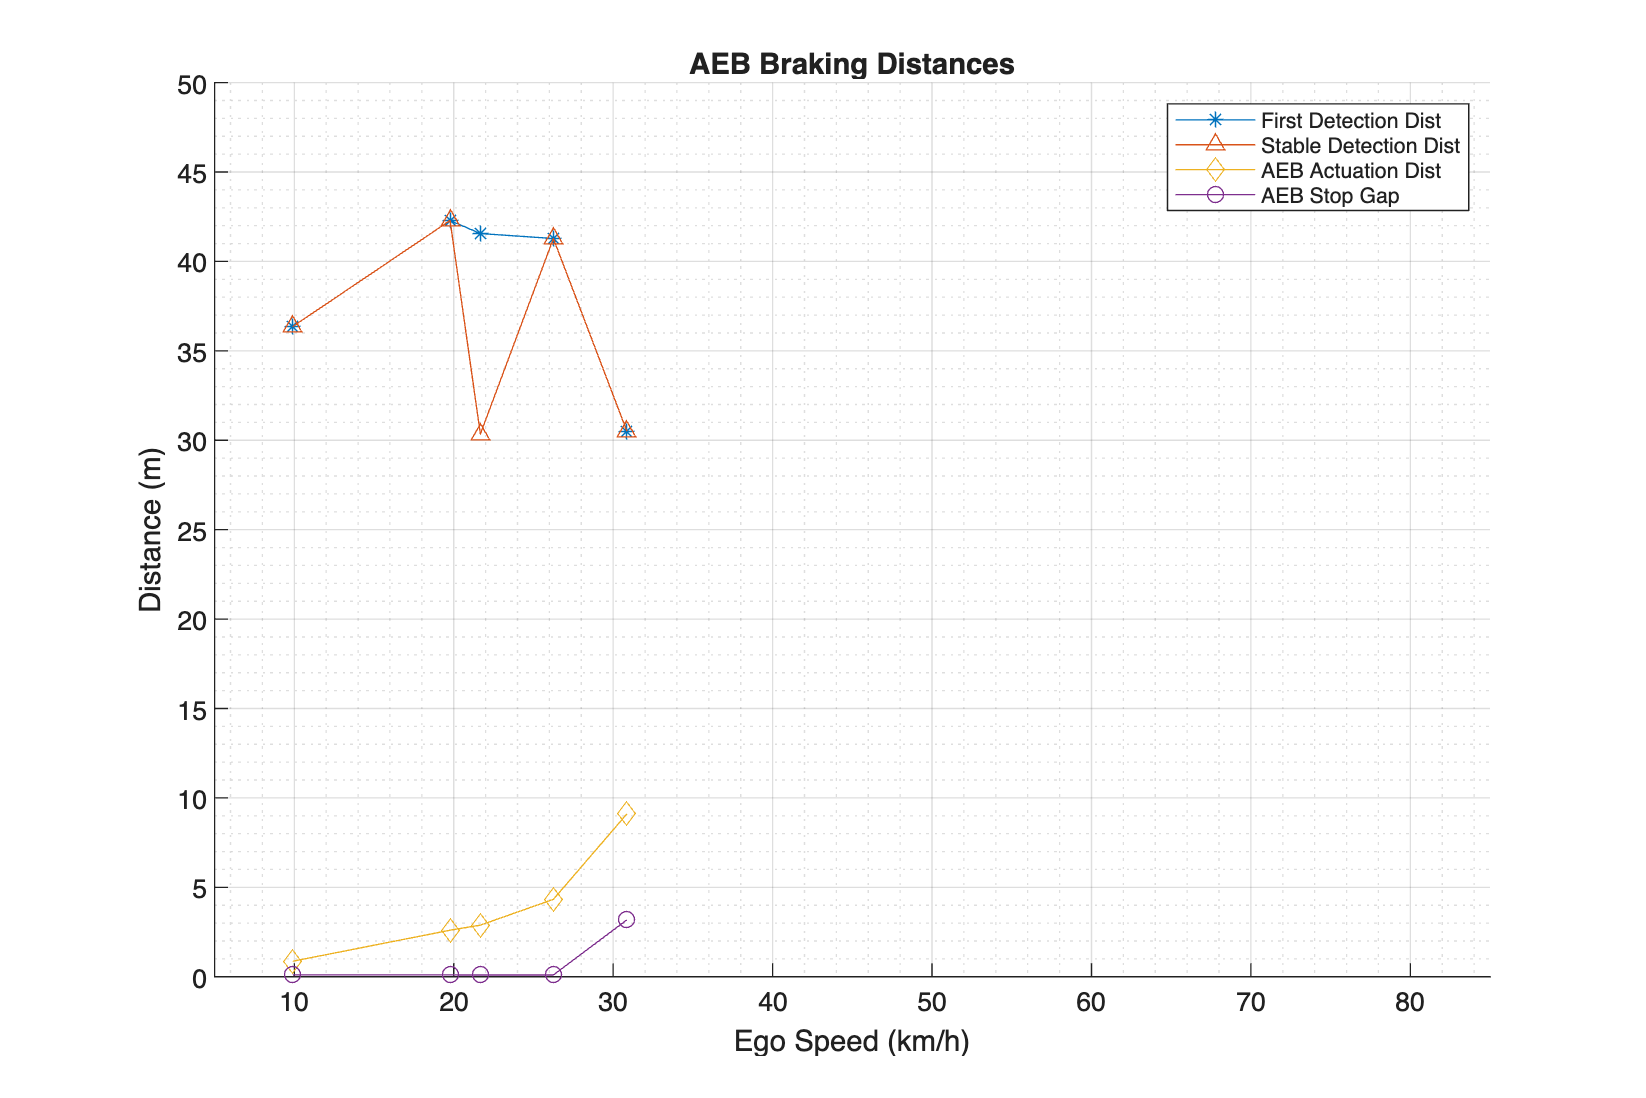

✅ AEB processing pipeline completed successfully.


aeb = AEBPipeline(configPath);

aeb.run();